Testul 4 - Balahura Vlad - grupa 231/1

Problema 1.

 a) Demonstrati ca $\Delta r\approx -\;\frac{\varepsilon g\left(r\right)}{f^{\prime } \left(x\right)}$

           Stiim ca r, radacina a lui f(x) => $f\left(r\right)=0$ 

           Cum $\Delta r+r$ solutie pentru     $f\left(x\right)+\varepsilon g\left(r\right)\Rightarrow f\left(\Delta r+r\right)+\varepsilon g\left(\Delta r+r\right)=0\;\;\;\left(1\right)$  

          Aplicam pentru $f\left(r+\Delta t\right)$ polinomul Taylor de ordin 1 cu $a=r$

                     $f\left(r+\Delta t\right)=f\left(r\right)+\Delta r\;f^{\prime } \left(r\right)$ , dar cum stiim ca $f\left(r\right)=0\Rightarrow$$f\left(r+\Delta t\right)=\Delta r\;{*f}^{\prime } \left(r\right)$

         Aplicam acelasi lucru si pentru $g\left(\Delta r+r\right)$, cu $a=r$

                            
$$g\left(\Delta r+r\right)=g\left(r\right)+\Delta r\;{*g}^{\prime } r$$


         Inlocuim $f\left(\Delta r+r\right)\;\mathrm{si}\;g\left(\Delta r+r\right)\;\mathrm{in}\;\left(1\right)\Rightarrow$ $$$\Delta r \cdot f'(r) + \epsilon \cdot [g(r) + \Delta r \cdot g'(r)] \approx 0$$ $

        Cum termenul $$\epsilon \cdot \Delta r \cdot g'(r)$$ este foarte foarte mic , il vom neglija => $$$\Delta r \cdot f'(r) + \epsilon g(r)= 0$$$ =>  $$$\Delta r \approx -\frac{\epsilon g(r)}{f'(r)}$$$

  b)

r_vechi = 6;
epsilon = -10^(-6);

g_r = r_vechi^7;
f_prim_r = prod(6 - (1:5)); 

delta_r = - (epsilon * g_r) / f_prim_r;
r_estimat_6 = r_vechi + delta_r;

fprintf('1. Estimarea radacinii de langa 6: %f\n', r_estimat_6);

1. Estimarea radacinii de langa 6: 6.002333




r_estimat_max = 1 / abs(epsilon);

fprintf('2. Estimarea celei mai mari radacini: %e\n\n', r_estimat_max);

2. Estimarea celei mai mari radacini: 1.000000e+06




coefs_f = poly(1:6);


P = [0, coefs_f]; 
P(1) = epsilon;


radacini_exacte = roots(P);
radacini_exacte = sort(radacini_exacte);


fprintf('Radacina exacta de langa 6 MATLAB: %f\n', radacini_exacte(6));

Radacina exacta de langa 6 MATLAB: 6.002327


fprintf('Cea mai mare radacina exacta MATLAB: %e\n', radacini_exacte(7));

Cea mai mare radacina exacta MATLAB: 9.999790e+05


Problema 2.

        
$$P\left(x\right)=x^{20} -\left(x-1\right)\left(x-2\right)\left(x-3\right)\left(x-4\right)\left(x-5\right)\left(x-6\right)$$


        Conditionarea coeficientiolor 

        Pentru un polinom $P\left(x\right)\;=\sum_{k=0}^n c_k x^k$,  calculam numarul de conditionare relativ la o radacina dupa formula $$$K(r) = \frac{\sum_{k=1}^{n} |a_k| \cdot |r|^{n-k}}{|r| \cdot |P'(r)|}$$$

Un numar de conditionare mare semnifica faptul ca polinomul este prost conditionat, adica erorile relative ale coeficientilor se amplifica semnificativ in radacini

polinom1 = zeros (1,21);
polinom1(1) = 1;

polinom2=poly(1:6);
polinom2 = [zeros(1,21 - length(polinom2)),polinom2];

P = polinom1 - polinom2;

radacini = roots(P);

for i = 1:length(radacini)
    xi = radacini(i);
    nr_cond = condpol(P, xi); 

    fprintf('Radacina %2d: %9.4f + %9.4f  | Cond: %e\n', ...
            i, real(xi), imag(xi), nr_cond);
end

Radacina  1:   -1.6000 +    0.0000  | Cond: 5.601095e-02
Radacina  2:   -1.4955 +    0.5488  | Cond: 6.046914e-02
Radacina  3:   -1.4955 +   -0.5488  | Cond: 6.046914e-02
Radacina  4:   -1.2006 +    1.0151  | Cond: 7.609759e-02
Radacina  5:   -1.2006 +   -1.0151  | Cond: 7.609759e-02
Radacina  6:   -0.7666 +    1.3334  | Cond: 1.115922e-01
Radacina  7:   -0.7666 +   -1.3334  | Cond: 1.115922e-01
Radacina  8:   -0.2666 +    1.4677  | Cond: 1.900908e-01
Radacina  9:   -0.2666 +   -1.4677  | Cond: 1.900908e-01
Radacina 10:    0.2217 +    1.4179  | Cond: 3.724191e-01
Radacina 11:    0.2217 +   -1.4179  | Cond: 3.724191e-01
Radacina 12:    0.6334 +    1.2161  | Cond: 8.213178e-01
Radacina 13:    0.6334 +   -1.2161  | Cond: 8.213178e-01
Radacina 14:    0.9294 +    0.9143  | Cond: 1.970093e+00
Radacina 15:    0.9294 +   -0.9143  | Cond: 1.970093e+00
Radacina 16:    1.0991 +    0.5666  | Cond: 4.975821e+00
Radacina 17:    1.0991 +   -0.5666  | Cond: 4.975821e+00
Radacina 18:    1.1494 +    0.2

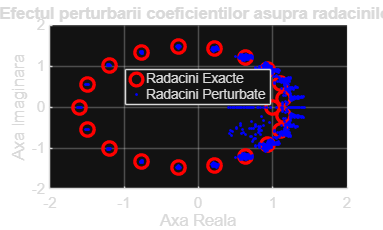


m = 100; 
dispersie = 1e-2; 
sigma = sqrt(dispersie); 


figure('Name', 'Experiment Perturbare', 'Color', 'w');
hold on; 
grid on;


plot(real(radacini), imag(radacini), 'ro', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName', 'Radacini Exacte');


for j = 1:m
  
    delta = sigma * randn(size(P)); 
    
    P_perturbat = P .* (1 + delta);
    
   
    radacini_pert = roots(P_perturbat);
    
   
    if j == 1
        plot(real(radacini_pert), imag(radacini_pert), 'b.', 'MarkerSize', 5, 'DisplayName', 'Radacini Perturbate');
    else
        plot(real(radacini_pert), imag(radacini_pert), 'b.', 'MarkerSize', 5, 'HandleVisibility', 'off');
    end
end

title('Efectul perturbarii coeficientilor asupra radacinilor');
xlabel('Axa Reala');
ylabel('Axa Imaginara');
legend('Location', 'best');
hold off;


function nr_cond=condpol(coefs,xi)
    coefs_der=polyder(coefs); 
    nr_cond = polyval(abs(coefs(2:end)), abs(xi)) / abs(xi * polyval(coefs_der, xi));
end
